# Linear Control Design 2 - Fall 2021 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E21) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**All exercises are equally weighted towards the overall assessment of the examination.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E21'

Exam = 'LCD2 E21'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Output feedback control of a test mass accelerometer

A test mass accelerometer is a measuring system utilized to measured vertical accelerations in e.g. vehicles. The figure below shows a simplified schematic of such device.

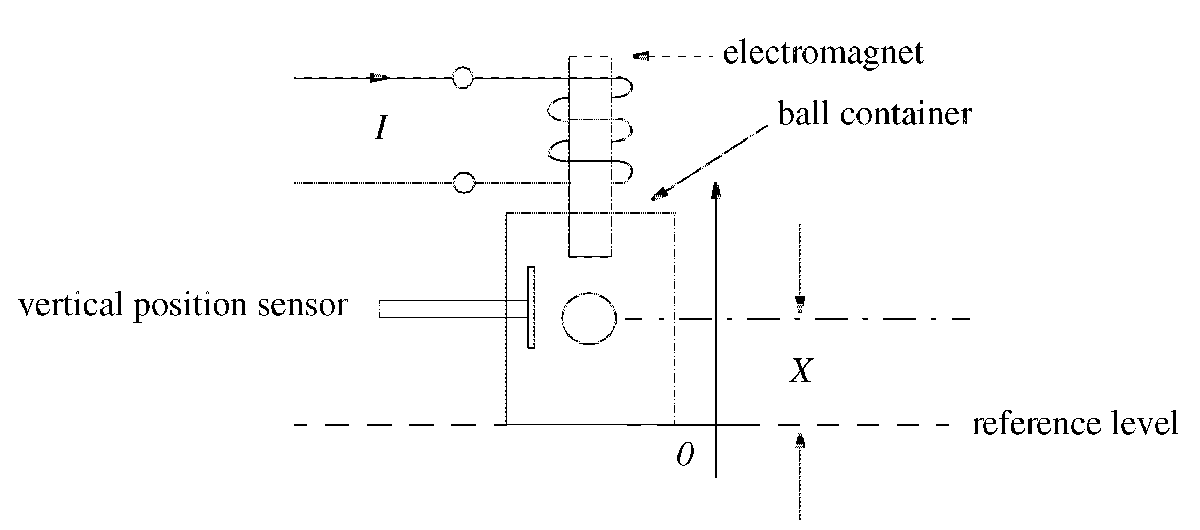

The test mass is a steel ball with a mass $m = 10\mathrm{g}$. The ball is held floating in a magnetic field by the electromagnet above it. The vertical position of the ball is measured by a position sensor.

The electromagnetic force that keeps the ball floating is given by


$$F_{em}(X,I) = 1.805\times10^3X^2 + 14.44XI - 6.498X + 0.02888I^2 + 0.374I - 0.1742$$


where $X$is the ball position (in meters) in relation to the reference point and $I$ is the current (in Amperes).

The ball is also influenced by the air resistance. The force that air resistance exerts on the ball is


$$F_{ar}(V) = -V(c_1 + c_2|V|)$$


where $c_1 = 1.55\times10^{-6}\mathrm{N}(m/s)$, $c_2 = 2.2\times 10^{-4}\mathrm{N(m/s)^2} $ and the ball's velocity $V$is expressed in $m/s$.

The accelerometer is under the influence of an external vertical acceleration $A$. The nonlinear model describing the motion of the ball reads


$$\frac{d^2X}{dt^2} = \frac{1}{m}F_{ar}(V)+\frac{1}{m}F_{em}(X,I) + A - g$$


where $g = 9.81\mathrm{m/s^2}$ is the acceleration of gravity.

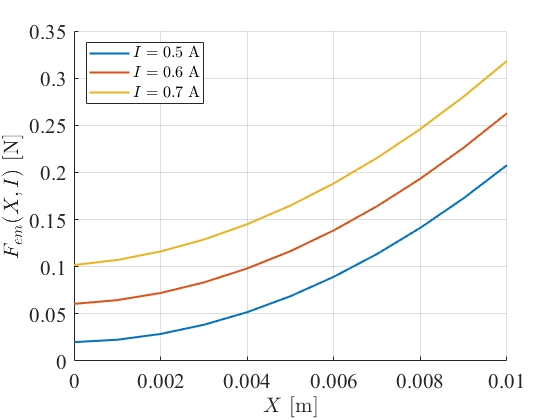

% Simulator parameters (RG)
SIM_TIME = 1; 
STEP_SIZE = 0.0001;
% Change with the name of the model you are using
SIMULINK_FILENAME = 'TestMassAccelerometer_NonlinearModel_Simulink2020b';

% Model paramters (RG)
m = 0.01; % mass in kilograms
c1 = 1.55*10^-6; % N*m/s
c2 = 2.2*10^-4; % N*m^2/s^2
% Coefficients of the electromagnetic force
f1 = 1.805*10^3; 
f2 = 14.44;
f3 = 6.498;
f4 = 0.02888;
f5 = 0.3740;
f6 = 0.1742;
% --------------------------------------------
g = 9.81; % m/s^2
A = 0; % m/s^2

% Electromagnetic force for different values of control current I (RG)
X = (0:0.001:0.01)'; % mass displacement range [m]
I0 = [0.5 0.6 0.7]; % control current [A]
for ii = 1:length(I0)
    F_em(:,ii) = f1*X.^2 + f2*X.*I0(ii) - f3*X + f4*I0(ii).^2 + f5*I0(ii) - f6;
end

figure, h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(X,F_em,'LineWidth',1.5)
ylabel('$F_{em}(X,I)$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
leg = legend('$I = 0.5$ A','$I = 0.6$ A','$I = 0.7$ A','Location','NorthWest');
set(leg,'FontName','times','FontSize',12,'Interpreter','latex')

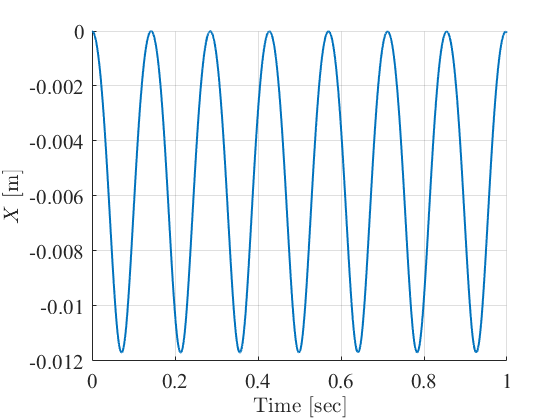

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = zeros(2,1); % initial condition x0 = [X,V]'
I0 = 0.5; % test current through the electromagnet [A]
I = I0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time I])

% Plot simulation result
t = logsout.getElement(1).Values.Time;
X = logsout.getElement(1).Values.Data;
V = logsout.getElement(2).Values.Data;

figure, h2 = axes; set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,X,'LineWidth',1.5)
ylabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 (2 points) **Determine the operating point associated with a nominal verical displacement of the mass $X_n = 2.5\mathrm{mm}$ when the external vertical acceleration $A=0$. Linearize the system around the operatig point.

% Your solution goes here


## Stability analysis

**Problem 2 (2 points)** Assess the internal and external stability of the linear system.

% Your solution goes here


## Control system design for measurement of external acceleration

The test mass accelerometer in opern loop is not capable of providing a measurement of the external vertical acceleration $A$. In order to enable the measuring device to provide such measurement a control system need to be designed.

Closed-loop system requirements

1) The position $X$ of the test mass is regulated to its nominal value $X_n$ despite step changes in the external vertical acceleration $A$.

2) For a step change in the external vertical acceleration $A$ equal to $0.25g$ at a time $t = t_{step}$ the position $X$ is regulated back to its nominal value $X_n$ with

        a) a maximum 20% deviation from its steady state value during the transient part of the response

        b) settling time between 50 and 75 milliseconds

Please refer to the following figure for a clear definition of the quantities described in the requirements. **IMPORTANT** The response shown in the figure (blue curve) serves only to display quantities of interest for the design requirements; therefore it does not necessarily represent the expected system behaviour.

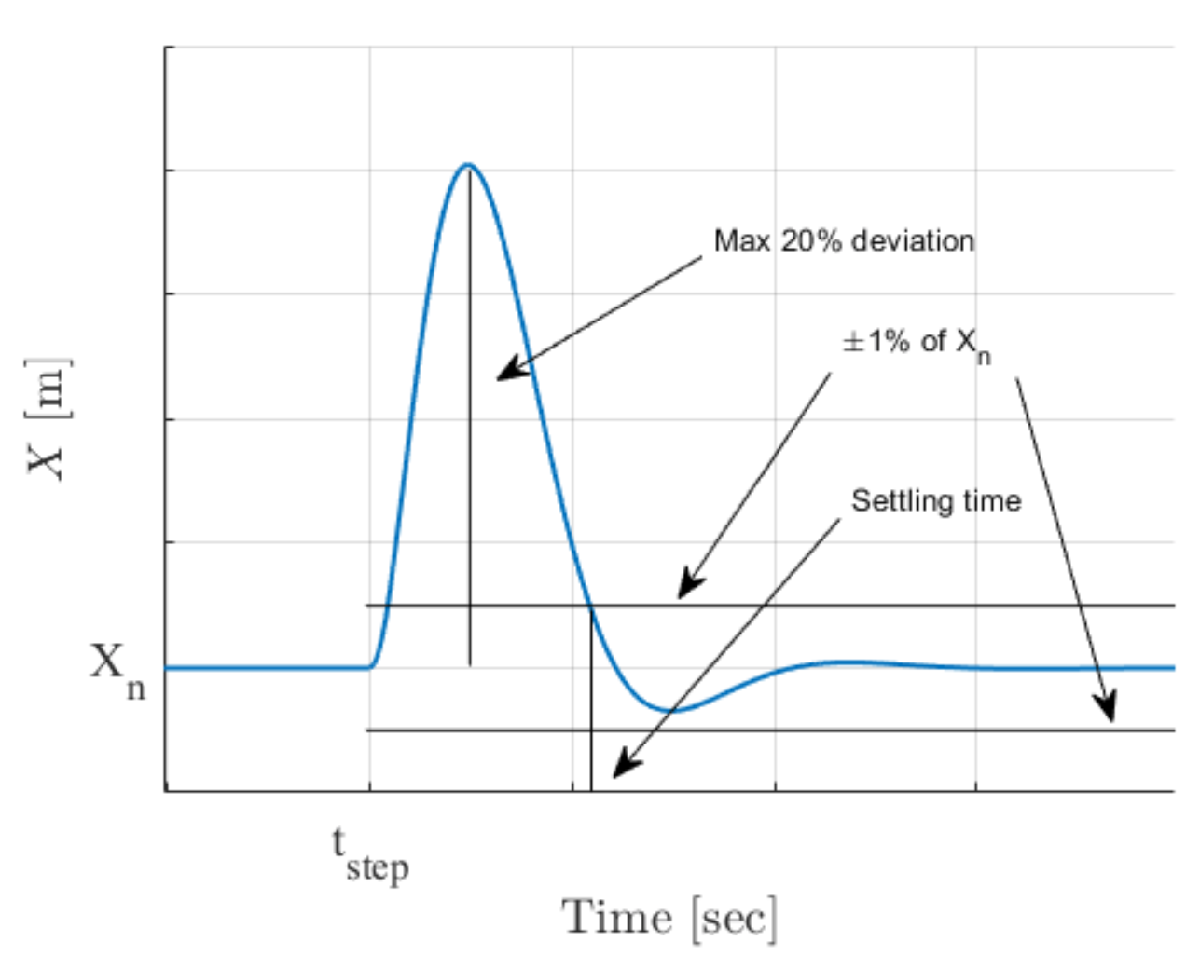

**Problem 3 (6 points)** Under the assumption that the state is fully accessible **design a discrete time optimal controller** that meets the aforementioned specifications on the nonlinear system.

% Your solution goes here


**Problem 4** **(2 points)** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to the step change in the external vertical acceleration $A$ of $0.25g$.

% Your solution goes here


## Observer design for estimation of the external acceleration

In order to determine the unknown acceleration $A$ acting on the measuring device a state estimator in the form of a Kalman filter can be employed.

The position measurement is affected by white noise $w$ with zero mean and noise intensity $V_w = 1\times10^{-10}$, i.e.


$$y = X + w$$


**Problem 5 (6 points)** Under the assumption that the exteral vertical acceleration is constant, **design a discrete time Kalman filter** able to reconstruct the state vector $x = [X,V]^\mathrm{T}$ and the unknown constant acceleration $A$. 

% Your solution goes here


**Problem 6 (4 points) **Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system, and assess the estimation performance of the Kalman filter when tested on the nonlinear system together with the control system designed in Problem 3, both in stationary conditions and in the presence of the step change in the external vertical acceleration $A$ of $0.25g$.

% Your solution goes here
